# Ziegler-Nichols


clc;clear all;close all;
s=tf('s');
Gs=10/(s*(s+1)*(s+2));
Ts=0.2

Ts = 0.2000

Gz=c2d(Gs,Ts,'zoh');

## 1er Paso, hallar kp=km, ganancia critica

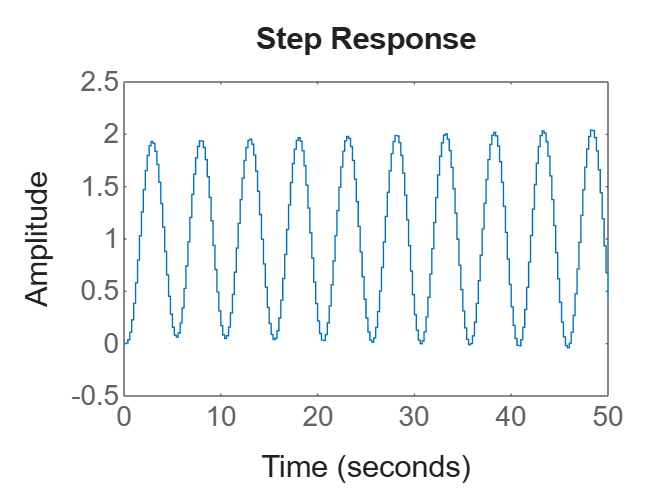

km=0.47;% cambias
K=km;
GCLz=feedback(K*Gz,1);
step(GCLz,50)

## 2do paso, hallar frecuencia de oscilacion del sistema marginalmente estable

tp2=48.2;
tp1=43.2;
Tosc=tp2-tp1;
wm=2*pi*1/Tosc %Hallas esto

wm = 1.2566

## 3er paso, usas formulas

kp=0.6*km;
kd=kp*pi/(4*wm);
ki=kp*wm/pi;
z=tf('z',Ts)


z =
 
  z
 
Sample time: 0.2 seconds
Discrete-time transfer function.
Model Properties


Kz=kp+ki*Ts/2*(z+1)/(z-1)+kd*(z-1)/(Ts*z);
GCLz=feedback(Kz*Gz,1)


GCLz =
 
  0.002703 z^4 + 0.004653 z^3 - 0.01212 z^2 + 0.003535 z + 0.001503
  ------------------------------------------------------------------
  0.2 z^5 - 0.6951 z^4 + 0.91 z^3 - 0.5295 z^2 + 0.1133 z + 0.001503
 
Sample time: 0.2 seconds
Discrete-time transfer function.
Model Properties


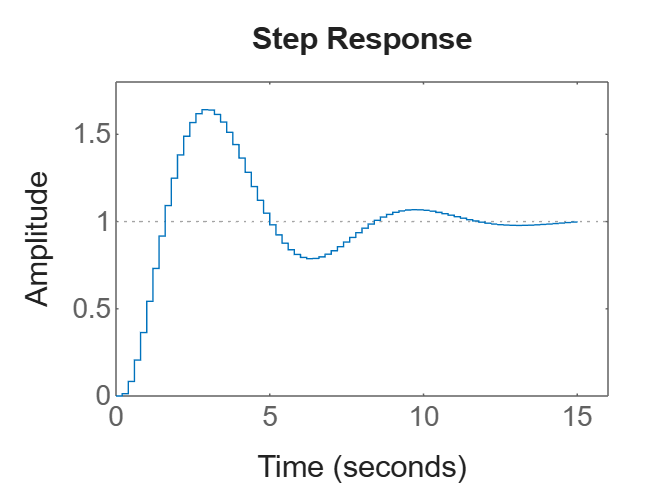

step(GCLz,15)


[Ganan_marginal,~,frec_marginal,~]=margin(Gz)% corroboras, km, wm

Gm = 0.4658

Wcg = 1.2397